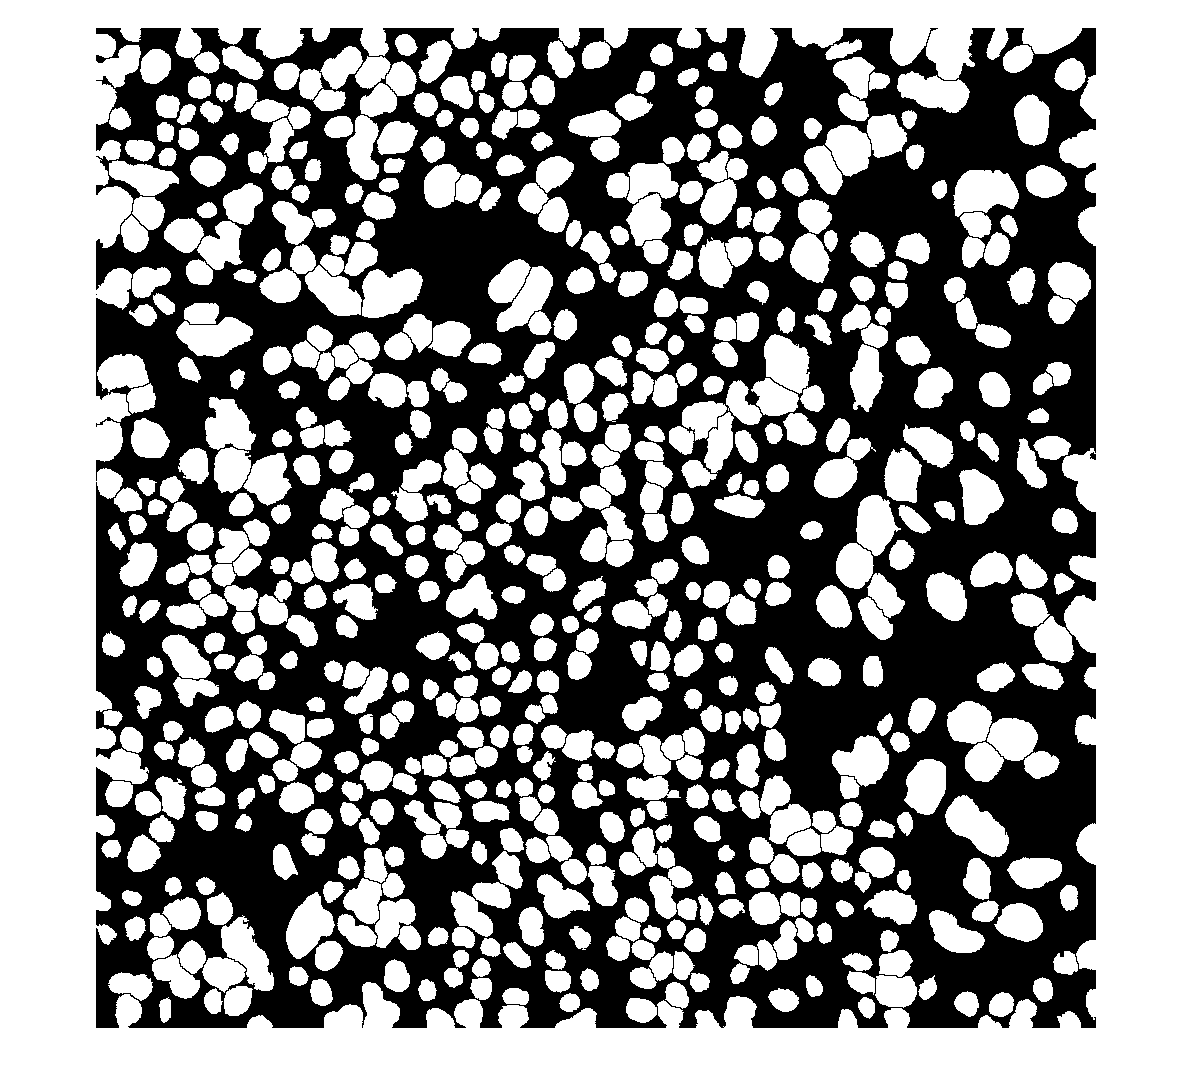

fn1 = "/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-44-2665-01B-06-BS6_prob_map_relu.mat";
H1=load(fn1);
BW1=fawshedsegm(H1.prob_map, 200, 'wthresh');
figure;
imshow(BW1);

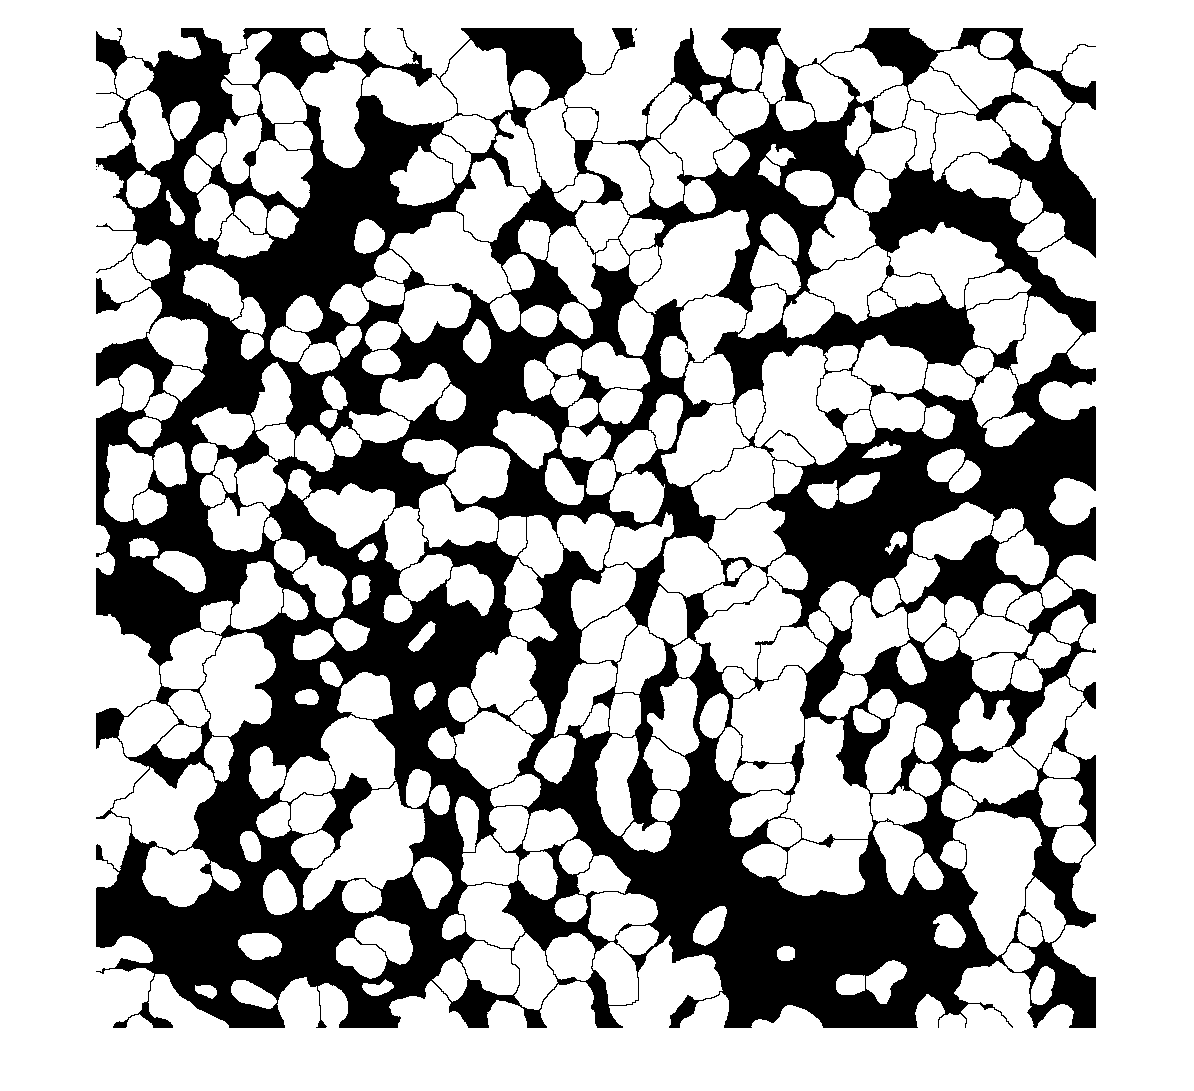

fn2 = "/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/sigmoid/TCGA-2Z-A9J9-01A-01-TS1_prob_map_sigmoid.mat";
H2=load(fn2);
BW2=fawshedsegm(H2.prob_map, 200, 'wthresh');
figure;
imshow(BW2);

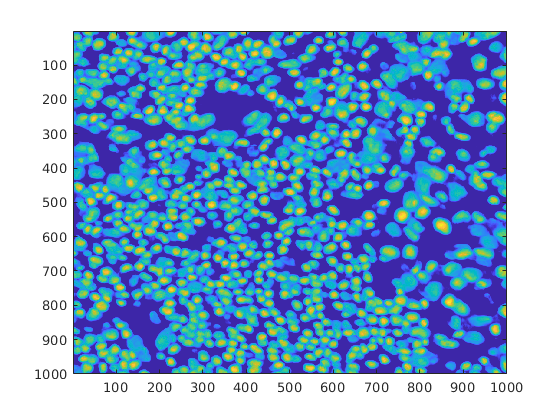

imagesc(H1.prob_map)

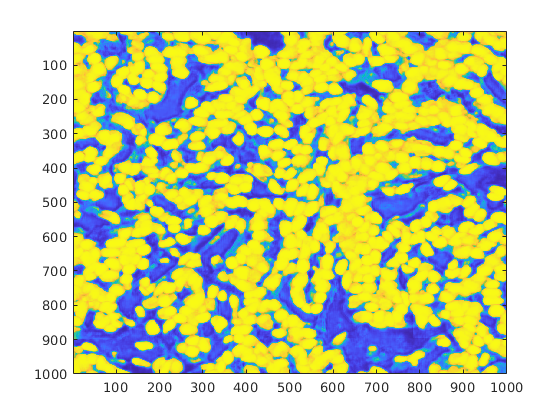

labels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

imagesc(H2.prob_map)


pat = "/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/";
outdir = "/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels";
fil=fullfile(pat,'*.mat');
d=dir(fil)

d = 14×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for k=1:numel(d)
  filename=fullfile(pat, d(k).name);
  fprintf(filename);
  
  H = load(filename);
  BW = fawshedsegm(H.prob_map, 200, 'wthresh');
  inst_map = bwlabel(BW);
  
  % [~, H, ~]=normalizeStaining(imread(filename));
  % BW=fawshedsegm(imcomplement(rgb2gray(H)), 200, 'wthresh');
  % BW = imopen(BW, se);
  % BW = medfilt2(BW);
  
  % new_name = strcat(d(k).folder, strrep(d(k).name, '.mat', '_mask.png'));
  % imwrite(BW, new_name);
  new_fn = fullfile(outdir, strrep(d(k).name, 'prob_map_relu.mat', 'relu_mask.mat'));
  fprintf(new_fn);
  save(new_fn, 'inst_map')
end

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-2Z-A9J9-01A-01-TS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-2Z-A9J9-01A-01-TS1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-44-2665-01B-06-BS6_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-44-2665-01B-06-BS6_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-69-7764-01A-01-TS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-69-7764-01A-01-TS1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-A6-6782-01A-01-BS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-A6-6782-01A-01-BS1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-AC-A2FO-01A-01-TS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-AC-A2FO-01A-01-TS1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-AO-A0J2-01A-01-BSA_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-AO-A0J2-01A-01-BSA_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-CU-A0YN-01A-02-BSB_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-CU-A0YN-01A-02-BSB_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-EJ-A46H-01A-03-TSC_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-EJ-A46H-01A-03-TSC_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-FG-A4MU-01B-01-TS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-FG-A4MU-01B-01-TS1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-GL-6846-01A-01-BS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-GL-6846-01A-01-BS1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-HC-7209-01A-01-TS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-HC-7209-01A-01-TS1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-HT-8564-01Z-00-DX1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-HT-8564-01Z-00-DX1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-IZ-8196-01A-01-BS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-IZ-8196-01A-01-BS1_relu_mask.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/probability_maps/V1/unet_smp_seresnet50_kumar/relu/TCGA-ZF-A9R5-01A-01-TS1_prob_map_relu.mat

/home/leos/IMAGE_ANALYSIS/model_ouputs/Kumar/result_segmentations/V1/unet_smp_seresnet50_kumar/nat_methods/Labels/TCGA-ZF-A9R5-01A-01-TS1_relu_mask.mat